# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network 

with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 24-Apr-2024 15:33:37

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([128 128 3],"Name","imageinput")
    convolution2dLayer([7 7],64,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    batchNormalizationLayer("Name","batchnorm")
    convolution2dLayer([1 1],64,"Name","conv_19","Padding","same")
    reluLayer("Name","relu_19")
    maxPooling2dLayer([5 5],"Name","maxpool_3","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_20","Padding","same")
    reluLayer("Name","relu_20")
    convolution2dLayer([3 3],64,"Name","conv_22","Padding","same")
    reluLayer("Name","relu_22")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_21","Padding","same")
    reluLayer("Name","relu_21")
    convolution2dLayer([5 5],64,"Name","conv_23","Padding","same")
    reluLayer("Name","relu_23")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_3")
    convolution2dLayer([1 1],64,"Name","conv_24","Padding","same")
    reluLayer("Name","relu_24")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_3")
    convolution2dLayer([1 1],64,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],64,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    convolution2dLayer([5 5],64,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat")
    convolution2dLayer([1 1],64,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    convolution2dLayer([1 1],64,"Name","conv_7","Padding","same")
    reluLayer("Name","relu_7")
    maxPooling2dLayer([5 5],"Name","maxpool_1","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_8","Padding","same")
    reluLayer("Name","relu_8")
    convolution2dLayer([3 3],64,"Name","conv_10","Padding","same")
    reluLayer("Name","relu_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_9","Padding","same")
    reluLayer("Name","relu_9")
    convolution2dLayer([5 5],64,"Name","conv_11","Padding","same")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_1")
    convolution2dLayer([1 1],64,"Name","conv_12","Padding","same")
    reluLayer("Name","relu_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    convolution2dLayer([1 1],64,"Name","conv_13","Padding","same")
    reluLayer("Name","relu_13")
    maxPooling2dLayer([5 5],"Name","maxpool_2","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_14","Padding","same")
    reluLayer("Name","relu_14")
    convolution2dLayer([3 3],64,"Name","conv_16","Padding","same")
    reluLayer("Name","relu_16")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],16,"Name","conv_15","Padding","same")
    reluLayer("Name","relu_15")
    convolution2dLayer([5 5],64,"Name","conv_17","Padding","same")
    reluLayer("Name","relu_17")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_2")
    convolution2dLayer([1 1],64,"Name","conv_18","Padding","same")
    reluLayer("Name","relu_18")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    convolution2dLayer([1 1],128,"Name","conv_25","Padding","same")
    reluLayer("Name","relu_25")
    globalAveragePooling2dLayer("Name","gapool")
    fullyConnectedLayer(10,"Name","fc")
    reluLayer("Name","relu_26")
    fullyConnectedLayer(8,"Name","fc_1")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"maxpool_3","conv_20");
lgraph = connectLayers(lgraph,"maxpool_3","conv_21");
lgraph = connectLayers(lgraph,"maxpool_3","addition_3/in2");
lgraph = connectLayers(lgraph,"relu_22","depthcat_3/in1");
lgraph = connectLayers(lgraph,"relu_23","depthcat_3/in2");
lgraph = connectLayers(lgraph,"relu_24","addition_3/in1");
lgraph = connectLayers(lgraph,"maxpool","conv_2");
lgraph = connectLayers(lgraph,"maxpool","conv_3");
lgraph = connectLayers(lgraph,"maxpool","addition/in2");
lgraph = connectLayers(lgraph,"relu_4","depthcat/in1");
lgraph = connectLayers(lgraph,"relu_5","depthcat/in2");
lgraph = connectLayers(lgraph,"relu_6","addition/in1");
lgraph = connectLayers(lgraph,"maxpool_1","conv_8");
lgraph = connectLayers(lgraph,"maxpool_1","conv_9");
lgraph = connectLayers(lgraph,"maxpool_1","addition_1/in2");
lgraph = connectLayers(lgraph,"relu_10","depthcat_1/in1");
lgraph = connectLayers(lgraph,"relu_11","depthcat_1/in2");
lgraph = connectLayers(lgraph,"relu_12","addition_1/in1");
lgraph = connectLayers(lgraph,"maxpool_2","conv_14");
lgraph = connectLayers(lgraph,"maxpool_2","conv_15");
lgraph = connectLayers(lgraph,"maxpool_2","addition_2/in2");
lgraph = connectLayers(lgraph,"relu_16","depthcat_2/in1");
lgraph = connectLayers(lgraph,"relu_17","depthcat_2/in2");
lgraph = connectLayers(lgraph,"relu_18","addition_2/in1");

## Plot Layers

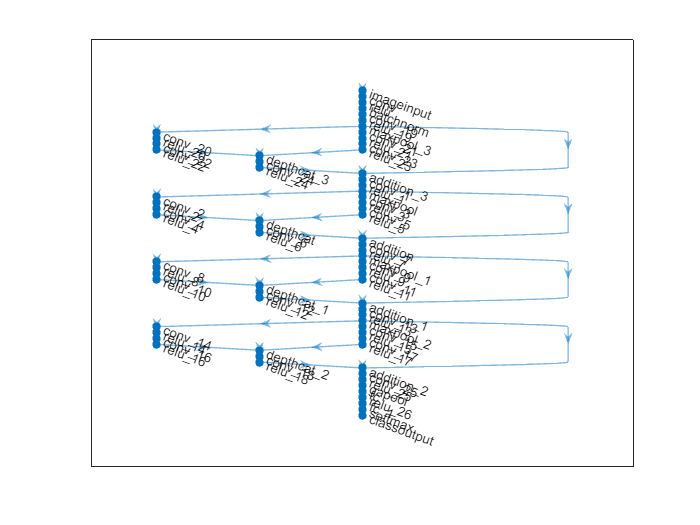

plot(lgraph);